# 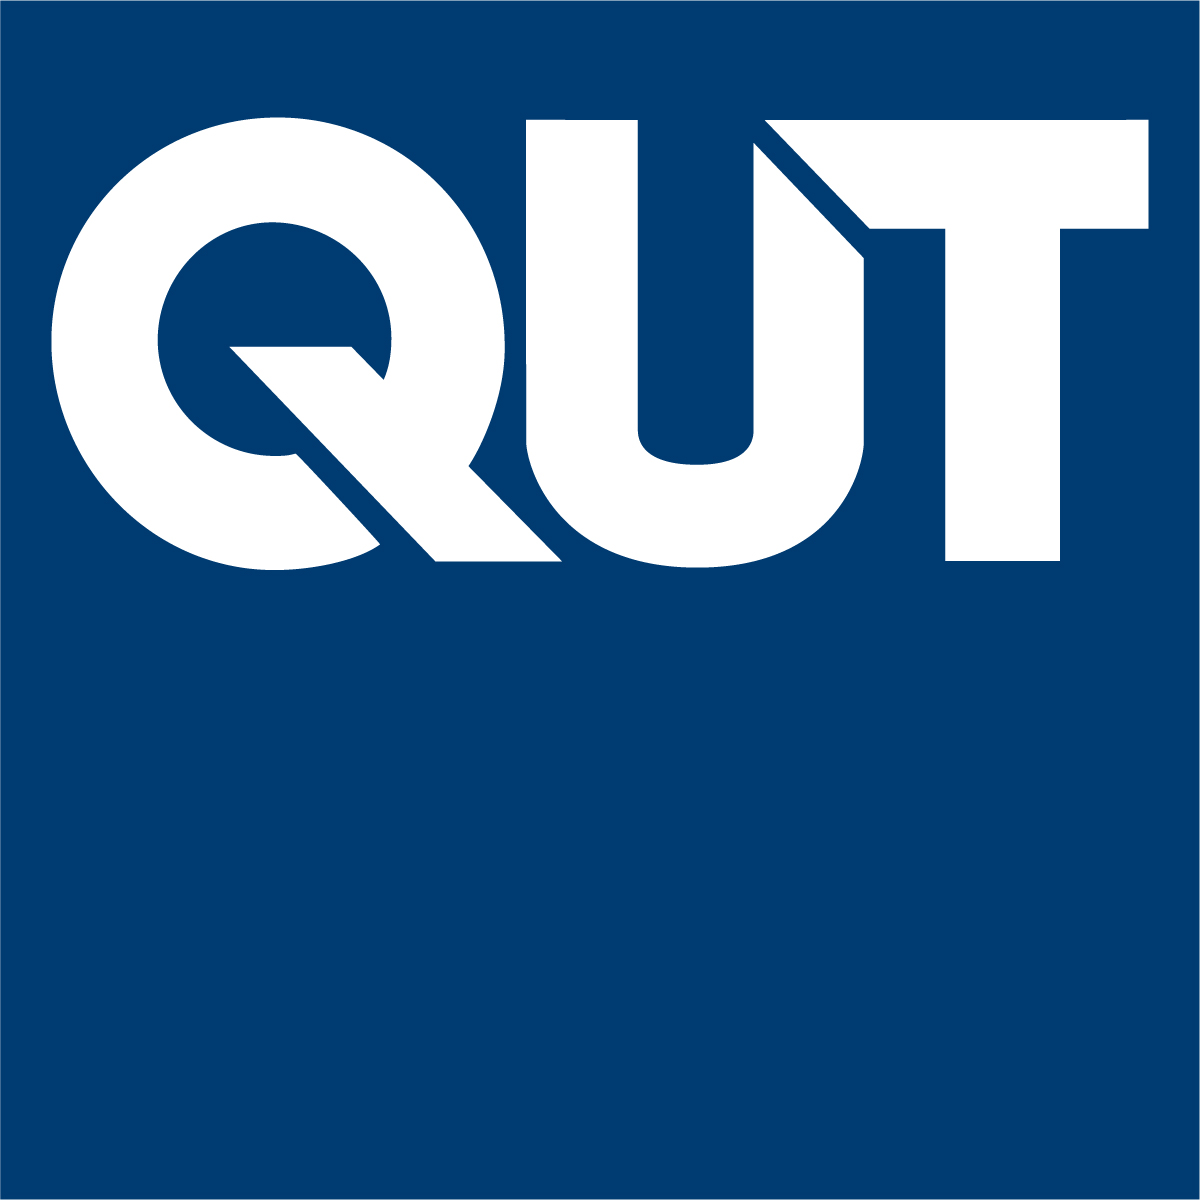

# MXB201 Chapter 1: Fundamental concepts in linear algebra

Professor Tim Moroney,  2022

V1.0

## 1.1 Introduction

If there is one subject that reaches across more of modern mathematical practice than any other, it is surely linear algebra.  Whether it's cranking out solutions to large-scale optimisation problems, high-performance simulations in scientific computing applications, uncovering statistical relationships in enormous data sets, or learning complex rules in a deep neural network, linear algebra is at the heart of it.

You already have a foundational understanding of important linear algebra concepts from your studies in MXB106.  In this unit, we will be greatly expanding our knowledge and widening the scope of problems that are within the reach of linear algebra techniques.

To begin with, in this chapter we will review many of the fundamental concepts in linear algebra, and possibly discover some interesting new facts along the way.  Our approach will be to analyse some progressively more "difficult", but in fact progressively more *interesting*, matrices.

These lecture notes are written in MATLAB Live Scripts.  They can be viewed in two ways:

- In MATLAB, by opening the .MLX file.  These are then in a sense, *interactive* lecture notes: you can edit or add to the code provided, experiment with the examples, change things, explore the effects, and so on.  Or, you can take the code as a starting point to develop your own ideas.

- On the web, by loading the .HTML file.  This has the advantage that the videos embed in the document, and it's portable (read and watch on your mobile, or whatever).  In that case you might like to have a copy of MATLAB open on the side to play around with the ideas while you're learning.  It's always best to participate in the process, rather than simply passively consume the content -- you'll learn much better that way!

## 1.2 Square, nonsingular matrix

We'll start our investigation with the simplest case of all: a square, nonsingular matrix.  Although you should pretend for the moment that you don't know whether it's nonsingular yet: that will be one of the first things we will verify.

In this chapter, we will use MATLAB's *symbolic* arithmetic.  This will enable us to focus on the theoretical issues under consideration.  (In later chapters, we will sometimes use floating point arithmetic.)

clear
n = 3;
A = sym([3 2 4 ; 4 1 2 ; 2 0 3]) % note the "sym" for a symbolic matrix

$$A = \left(\begin{array}{ccc} 3 & 2 & 4\\ 4 & 1 & 2\\ 2 & 0 & 3 \end{array}\right)$$

### 1.2.1 Reduction to row echelon form

First, let's revise how we perform row reduction using type 3 row operations by hand.

[Video](https://web.microsoftstream.com/video/572fa237-be35-40b9-8fc3-2a3c04d7800f)

#### Exercise

On a piece of paper, perform this same sequence of row operations yourself by hand.  Don't refer to back to the example video unless you really get stuck.▫

Having done the work yourself by hand, you might agree that it would be preferable for the computer to do this tedious work for you as much as possible in the future.  In fact, in the Real World™ *nobody* does row operations by hand.  Why would you, when computers are many, many, many *orders of magnitude *faster and better at it than we are?

So it's important to learn how to do things programatically -- that is, by writing code.  In this unit, we'll work our examples side-by-side on paper, and in MATLAB.  We do them on paper first to get the idea straight in our head.  Then we do them in MATLAB so we never have to do them by hand ever again!

So, let's see how to apply the same sequence of type 3 row operations in MATLAB.

R = A; % make a copy, so we don't overwrite the original matrix
R(2,:) = R(2,:) - R(2,1)/R(1,1) * R(1,:) % syntax is reminiscent of how we would write it by hand

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 2 & 0 & 3 \end{array}\right)$$

R(3,:) = R(3,:) - R(3,1)/R(1,1) * R(1,:)

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & -\frac{4}{3} & \frac{1}{3} \end{array}\right)$$

R(3,:) = R(3,:) - R(3,2)/R(2,2) * R(2,:)

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & 0 & 3 \end{array}\right)$$

#### Exercise

In a (separate) MATLAB editor tab, perform this same sequence of row operations yourself.  Don't refer to back to the example code unless you really get stuck.▫

### 1.2.2 Row rank

Now that we have our echelon form, what information can we learn from it?

[Video](https://web.microsoftstream.com/video/8837ae6d-6afc-490f-b131-a3bb678699f9)

So the row echelon form reveals that this matrix is nonsingular.  Here's the argument summarised:

- Type 3 row operations replace a row with a linear combination of itself and another row.

- Hence, the *span* of the row vectors is unchanged by these row operations.

- Hence, the row space of $R$ is the *same space* as the row space of $A$ (just expressed in terms of different vectors).

- From the structure of the zeros in the echelon form, it is clear that no row in the eliminated matrix can be expressed linearly in terms of the others..

- Hence all rows of $R$ are linearly independent.

- Hence the row space of $R$, which is the same as the row space of $A$ remember, has dimension 3.

- Hence $A$ has *rank* of 3 (recall the *rank* is the dimension of the row space).

Furthermore, we can readily calculate the determinant of $A$ from this echelon form.  Since we used only type 3 row operations, which don't alter the determinant, the determinant of $R$ is the determinant of $A$.

prod(diag(R)) % determinant of a triangular matrix is the product of the diagonal elements

$$ans = -15$$

isequal(ans, det(A)) % let's confirm this equals det(A)

ans = logical
   1

The determinant is nonzero for a nonsingular matrix.

### 1.2.3 Solving a linear system

We could also use this echelon form to solve a linear system of equations $Ax=b$.

First, let's revise how we perform row reduction with an *augmented *matrix, followed by backward substitution, by hand.

[Video](https://web.microsoftstream.com/video/1ba46a88-8a9e-4a58-8d50-54ce7c6b0a4a)

#### Exercise

On a piece of paper, apply this same process to solve the same linear system yourself.  Don't refer to back to the example video unless you really get stuck.▫

Now we'll do it in MATLAB.

b = sym([5; 0; 7]) % the right hand side vector

$$b = \left(\begin{array}{c} 5\\ 0\\ 7 \end{array}\right)$$

Typically we would augment the matrix and right hand side first:


$$[A\ b]$$


and apply the row operations to reduce the augmented system to


$$[R \ z]$$


from which point we could apply backward substitution to easily find $x$.

Like so:

R_z = [A b] % augment the matrix and right hand side

$$R\_z = \left(\begin{array}{cccc} 3 & 2 & 4 & 5\\ 4 & 1 & 2 & 0\\ 2 & 0 & 3 & 7 \end{array}\right)$$

R_z(2,:) = R_z(2,:) - R_z(2,1)/R_z(1,1) * R_z(1,:) % same row operations as previously

$$R\_z = \left(\begin{array}{cccc} 3 & 2 & 4 & 5\\ 0 & -\frac{5}{3} & -\frac{10}{3} & -\frac{20}{3}\\ 2 & 0 & 3 & 7 \end{array}\right)$$

R_z(3,:) = R_z(3,:) - R_z(3,1)/R_z(1,1) * R_z(1,:) % same row operations as previously

$$R\_z = \left(\begin{array}{cccc} 3 & 2 & 4 & 5\\ 0 & -\frac{5}{3} & -\frac{10}{3} & -\frac{20}{3}\\ 0 & -\frac{4}{3} & \frac{1}{3} & \frac{11}{3} \end{array}\right)$$

R_z(3,:) = R_z(3,:) - R_z(3,2)/R_z(2,2) * R_z(2,:) % same row operations as previously

$$R\_z = \left(\begin{array}{cccc} 3 & 2 & 4 & 5\\ 0 & -\frac{5}{3} & -\frac{10}{3} & -\frac{20}{3}\\ 0 & 0 & 3 & 9 \end{array}\right)$$

R = R_z(:, 1:n), z = R_z(:, n+1) % pull out the "R" part and the "z" part separately

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & 0 & 3 \end{array}\right)$$

$$z = \left(\begin{array}{c} 5\\ -\frac{20}{3}\\ 9 \end{array}\right)$$

x = R \ z  % MATLAB solves by substitution when you backslash a triangular matrix

$$x = \left(\begin{array}{c} -1\\ -2\\ 3 \end{array}\right)$$

#### Exercise

In a (separate) MATLAB editor tab, perform this same sequence of row operations yourself, and the substitution step.  Don't refer to back to the example code unless you really get stuck.▫

Notice how you're duplicating your work here!  (I don't mean by doing things by hand first, and then in MATLAB again -- that's good practice.)  I mean that we already applied all these row operations once already to $A$, but now we're applying them all over again to the augmented matrix $[A|b]$.  If only we had a convenient mechanism for *recording* the row operations we used in the first place, so that we could essentially *replay* those same operations applied to just $b$.  How might we go about recording the sequence of row operations we used in a convenient form?

### 1.2.4 Elementary matrices

To record the sequence of row operations applied, we can use *elementary matrices*: these are identity matrices that have had the relevant row operation performed on them.

[Video](https://web.microsoftstream.com/video/e5eee5f2-455e-4639-b481-3eb57878e04a)

Let's set up what we need in MATLAB.

I = sym(eye(n)) % identity matrix will come in handy

$$I = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

R = A % we will apply row operations progressively to this matrix R

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 4 & 1 & 2\\ 2 & 0 & 3 \end{array}\right)$$

The first row operation we want to perform on $R$ is `R(2,:) = R(2,:) - R(2,1)/R(1,1) * R(1,:)`

Instead of applying that operation directly to $R$, we instead apply it to $I$ to produce a matrix we'll call $E_1$.

E1 = I;
E1(2,:) = E1(2,:) - R(2,1)/R(1,1) * E1(1,:) % apply the row operation to I to get E1

$$E1 = \left(\begin{array}{ccc} 1 & 0 & 0\\ -\frac{4}{3} & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

This *elementary matrix* $E_1$ encodes the row operation we intend to apply to $R$.  We can apply the row operation to $R$ by pre-multiplying  by $E_1$.  [Anton 1.5]

R = E1 * R

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 2 & 0 & 3 \end{array}\right)$$

We can repeat this process for the remaining two row operations.

% R(3,:) = R(3,:) - R(3,1)/R(1,1) * R(1,:)
E2 = I; E2(3,:) = E2(3,:) - R(3,1)/R(1,1) * E2(1,:)

$$E2 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ -\frac{2}{3} & 0 & 1 \end{array}\right)$$

R = E2 * R

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & -\frac{4}{3} & \frac{1}{3} \end{array}\right)$$

% R(3,:) = R(3,:) - R(3,2)/R(2,2) * R(2,:)
E3 = I; E3(3,:) = E3(3,:) - R(3,2)/R(2,2) * E3(2,:)

$$E3 = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & -\frac{4}{5} & 1 \end{array}\right)$$

R = E3 * R

$$R = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & 0 & 3 \end{array}\right)$$

Now that we have the row operations recorded in the form of elementary matrices, we can easily replay them again at any time.  Here's the full sequence replayed again:

E3 * E2 * E1 * A

$$ans = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & 0 & 3 \end{array}\right)$$

isequal(ans, R)  % yep, that's equal to our row echelon form

ans = logical
   1

Clearly we can parcel this sequence of elementary matrices all up into a single matrix $E$.  We'll call $E$ the *elimination matrix*.

E = E3 * E2 * E1

$$E = \left(\begin{array}{ccc} 1 & 0 & 0\\ -\frac{4}{3} & 1 & 0\\ \frac{2}{5} & -\frac{4}{5} & 1 \end{array}\right)$$

isequal(R, E*A)  % the elimination matrix E applied to A produces R

ans = logical
   1

Note that $E$ is *not *an elementary matrix; that term is reserved for a single row operation applied to the identity, not a sequence of two or more.

Using this elimination matrix $E$, we can easily solve a linear system $Ax=b$

z = E * b  % apply elimination matrix to b (i.e. apply the row operations to b)

$$z = \left(\begin{array}{c} 5\\ -\frac{20}{3}\\ 9 \end{array}\right)$$

x = R \ z  % solve by back substitution

$$x = \left(\begin{array}{c} -1\\ -2\\ 3 \end{array}\right)$$

isequal(A*x, b)  % yep, A*x equals b

ans = logical
   1

Observe that the vector $z$ we obtained is the same as we had earlier when we applied row operations to the augmented matrix.  But notice how easy it is now to change our mind and solve for a *different* $b$: we could just replay the operations to the new $b$.  Or even solve for a new right hand side $b$ that wasn't available when we performed the elimination on $A$.  Saving the row operations in an elimination matrix gives you more options.

#### Exercise

In a (separate) MATLAB editor tab, build this same sequence of elementary matrices yourself, compute the elimination matrix $E$, and use it to solve $Ax=b$.  Don't refer to back to the example code unless you really get stuck.▫

### **1.2.5 Relation to LU decomposition**

**ASIDE**

If you have studied computational linear algebra, you might be wondering how this idea relates to the LU decomposition of $A$.  Glad you asked!

The LU decomposition returns a unit lower triangular matrix $L$ and an upper triangular matrix $U$ such that $A = LU$.

[L,U] = lu(A)

$$L = \left(\begin{array}{ccc} 1 & 0 & 0\\ \frac{4}{3} & 1 & 0\\ \frac{2}{3} & \frac{4}{5} & 1 \end{array}\right)$$

$$U = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & 0 & 3 \end{array}\right)$$

isequal(A, L*U)

ans = logical
   1

  In fact, $U$ is simply our row echelon form $R$.

isequal(U, R)

ans = logical
   1

Since we know that simultaneously $R = EA$ and $A = LU$, it must be that $L = E^{-1}$.

inv(E)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ \frac{4}{3} & 1 & 0\\ \frac{2}{3} & \frac{4}{5} & 1 \end{array}\right)$$

isequal(ans, L)

ans = logical
   1

So the LU decomposition is based on the same idea of recording the row operations in a matrix, just from a slightly different point of view.

**END ASIDE**

Before we move on, it's worth thinking about how best to actually build this elimination matrix $E$ in the computer.  You did it the "hard way" yourself earlier, but here's a nifty idea: suppose we augment our matrix $A$ with the *identity* $I$ at the outset.

R_E = [A I]

$$R\_E = \left(\begin{array}{cccccc} 3 & 2 & 4 & 1 & 0 & 0\\ 4 & 1 & 2 & 0 & 1 & 0\\ 2 & 0 & 3 & 0 & 0 & 1 \end{array}\right)$$

Once more for fun, we go through the same sequence of row operations we've applied many times before:

R_E(2,:) = R_E(2,:) - R_E(2,1)/R_E(1,1) * R_E(1,:);
R_E(3,:) = R_E(3,:) - R_E(3,1)/R_E(1,1) * R_E(1,:);
R_E(3,:) = R_E(3,:) - R_E(3,2)/R_E(2,2) * R_E(2,:)  % only display the final step this time

$$R\_E = \left(\begin{array}{cccccc} 3 & 2 & 4 & 1 & 0 & 0\\ 0 & -\frac{5}{3} & -\frac{10}{3} & -\frac{4}{3} & 1 & 0\\ 0 & 0 & 3 & \frac{2}{5} & -\frac{4}{5} & 1 \end{array}\right)$$

But notice: by augmenting the identity and applying the same row operations to it, we have actually recorded the full elimination matrix $E$ as we went along.  It's just sitting there in the rightmost columns.

R_E(:, n+1:end)

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ -\frac{4}{3} & 1 & 0\\ \frac{2}{5} & -\frac{4}{5} & 1 \end{array}\right)$$

isequal(ans, E) % the right half is E

ans = logical
   1

Meanwhile the row echelon form is still there on the left as usual.

R_E(:, 1:n)

$$ans = \left(\begin{array}{ccc} 3 & 2 & 4\\ 0 & -\frac{5}{3} & -\frac{10}{3}\\ 0 & 0 & 3 \end{array}\right)$$

isequal(ans, R) % the left half is R

ans = logical
   1

Very nice.  So we don't have to go through the side process of forming individual elementary matrices $E_1$, $E_2$ and so on.  We can just augment $A$ with $I$, apply our sequence of row operations directly, and read off *both* the row echelon form $R$ and the elimination matrix $E$ at the end.

#### Exercise

In a (separate) MATLAB editor tab, use the process described above to compute the row echelon form $R$ and the elimination matrix $E$, and use it to solve $Ax=b$.  Don't refer to back to the example code unless you really get stuck.▫

### 1.2.6 Reduction to reduced row echelon form (RREF)

Row echelon form is sufficient to calculate determinants and solve linear systems, and so row echelon form is all you would ever need if that was your *only* goal.  Since our goal is also to advance our *theoretical understanding* we will continue with our elimination process from here, all the way to *reduced* row echelon form.  This means, scaling the pivots to be ones, and zeroing *above* the pivots as well.  The algorithm should be familiar already from your earlier studies, but if not, refer to the text book for details. [Anton 1.1]

[Video](https://web.microsoftstream.com/video/7d084993-5c78-47a5-97ef-6f29afb0ba91)

We will *not* ask you to go through the pain of doing this whole example yourself by hand.  Although feel free all the same, if you really want to.

Let's jump straight in to finding the RREF in MATLAB by applying the remaining row operations required.  Remember that in MATLAB we're applying the row operations to the augmented matrix $[A|I]$, so that we get both the reduced row echelon form $R$ *and *the elimination matrix $E$ at the end.

% Scale the rows to have unit pivots
R_E(1,:) = R_E(1,:) / R_E(1,1);
R_E(2,:) = R_E(2,:) / R_E(2,2);
R_E(3,:) = R_E(3,:) / R_E(3,3) % only show the final result

$$R\_E = \left(\begin{array}{cccccc} 1 & \frac{2}{3} & \frac{4}{3} & \frac{1}{3} & 0 & 0\\ 0 & 1 & 2 & \frac{4}{5} & -\frac{3}{5} & 0\\ 0 & 0 & 1 & \frac{2}{15} & -\frac{4}{15} & \frac{1}{3} \end{array}\right)$$

% Introduce zeros above the pivots
R_E(2,:) = R_E(2,:) - R_E(2,3) * R_E(3,:);
R_E(1,:) = R_E(1,:) - R_E(1,3) * R_E(3,:);
R_E(1,:) = R_E(1,:) - R_E(1,2) * R_E(2,:) % only show the final result

$$R\_E = \left(\begin{array}{cccccc} 1 & 0 & 0 & -\frac{1}{5} & \frac{2}{5} & 0\\ 0 & 1 & 0 & \frac{8}{15} & -\frac{1}{15} & -\frac{2}{3}\\ 0 & 0 & 1 & \frac{2}{15} & -\frac{4}{15} & \frac{1}{3} \end{array}\right)$$

Because our matrix $A$ is nonsingular, its reduced row echelon form is simply the identity matrix.

isequal(R_E(:, 1:n), I)

ans = logical
   1

So what, then, is sitting in the rightmost columns?  Well, as always, it's the cumulative effect of all our row operations.  It's the matrix $E$, such that when applied to $A$, reduces $A$ to the identity matrix (since the identity matrix *is* the reduced row echelon form of $A$).

E_rref = R_E(:, n+1:end)

$$E\_rref = \left(\begin{array}{ccc} -\frac{1}{5} & \frac{2}{5} & 0\\ \frac{8}{15} & -\frac{1}{15} & -\frac{2}{3}\\ \frac{2}{15} & -\frac{4}{15} & \frac{1}{3} \end{array}\right)$$

E_rref * A  % confirm that it reduces A to the identity

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

Which is to say, $E$ is now just the *inverse* of $A$: $E = A^{-1}$.

isequal(E_rref, inv(A))

ans = logical
   1

This is in fact the *Gauss-Jordan* method for finding the inverse of a matrix.  But now you can see why it works: the inverse matrix *is* the sequence of row operations that reduces $A$ to the identity.

#### Exercise

In a (separate) MATLAB editor tab, use the process described above to compute the inverse matrix $A^{-1}$ by Gauss-Jordan elimination.  Don't refer to back to the example code unless you really get stuck.▫

### 1.2.7 The MATLAB functions rref and rref2

As already alluded to, for solving practical problems, finding the reduced row echelon form is usually too much work to be worth it.  But for theoretical understanding, it has a decided advantage: it is *unique*.  Any matrix $A$ has exactly one reduced row echelon form.  Hence, the particular sequence of row operations used to calculate it is unimportant: everyone will agree on the final result.

MATLAB handily provides a function for finding the RREF, called unsurprisingly, `rref`.

R = rref(A)

$$R = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

From now on in this chapter, we'll only deal with RREFs, so our notation $R$ will always refer to the *reduced *row echelon form.  For our current matrix $A$, its RREF is just the identity, but that won't be the case for every matrix.

Annoyingly, MATLAB's `rref` *doesn't *return the elimination matrix, so there's no way of replaying the row operations again later (say, to a right hand side vector).  To remedy this, your lecturer has written an improved function called `rref2` that also returns the elimination matrix.  We already know how to do this ourselves: just augment the matrix with the identity at the beginning, and then pull apart the two halves at the end.  (You might like to check the code of `rref2.m` to confirm that's exactly how it works.)

[R,E] = rref2(A)  % using our own function rref2, we also get the elimination matrix

$$R = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

$$E = \left(\begin{array}{ccc} -\frac{1}{5} & \frac{2}{5} & 0\\ \frac{8}{15} & -\frac{1}{15} & -\frac{2}{3}\\ \frac{2}{15} & -\frac{4}{15} & \frac{1}{3} \end{array}\right)$$

isequal(E, inv(A)) % A is invertible, so the elimination matrix is its inverse

ans = logical
   1

Having gone to the trouble of computing a full RREF, it's trivial to then solve $Ax = b$ for this example.  The solution can be read off directly from the reduced right hand side vector.

E * [A b]  % RREF, so the solution to Ax = b will be the rightmost column

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & -1\\ 0 & 1 & 0 & -2\\ 0 & 0 & 1 & 3 \end{array}\right)$$

x = E * b  % or better yet, here's just that column

$$x = \left(\begin{array}{c} -1\\ -2\\ 3 \end{array}\right)$$

#### Exercise

In a (separate) MATLAB editor tab, use the `rref2` function to solve $Ax=b$.  Don't refer to back to the example code unless you really get stuck.▫

### 1.2.8 Consistency of a linear system

We know from our earlier analysis that this matrix $A$ is nonsingular.  Hence, for *any* right hand side vector $b$ the linear system $Ax=b$ will be consistent and have a unique solution.  It's worthwhile considering how best to characterise this fact in a way that will generalise to more interesting cases.  The most useful way turns out to be using the rank of the matrices $A$ and $[A \ b]$.

[Video](https://web.microsoftstream.com/video/9f88d112-e1ec-47e8-bdc5-03d4b575f46e)

If we have our elimination matrix $E$, we can calculate these two ranks by counting the number of nonzero rows in the reduced row echelon forms:

E*A

$$ans = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1 \end{array}\right)$$

E*[A b]

$$ans = \left(\begin{array}{cccc} 1 & 0 & 0 & -1\\ 0 & 1 & 0 & -2\\ 0 & 0 & 1 & 3 \end{array}\right)$$

In both cases, there are 3 nonzero rows and hence the ranks of $A$ and $[A \ b]$ are both 3.  You actually could have read *both* ranks off just the second matrix (i.e. just the augmented matrix) by mentally covering up the right hand side column at first.

We could also have just asked MATLAB directly:

rank(A), rank([A b])

ans = 3

ans = 3

but of course this isn't magic: the `rank` function has to do the same elimination as us to get the answer.

Anyway, however you arrive at the answer, the first key fact is that rank($A$) = rank($[A\ b]$) which means the system is *consistent*.

- rank($A$) = rank($[A\ b]$)  $\iff$  system is **consistent**

To ascertain whether the solution is *unique* or not, you need to ask whether this common rank is equal to the number of unknowns $n$:

isequal(rank(A), n)

ans = logical
   1

In this case, yes it is.  So the system has a *unique *solution.

- rank($A$) = rank($[A\ b]$)  = $n$ $\iff$  system is **consistent **with a **unique** solution

If this seemed like an unnecessarily elaborate way to determine the number of solutions to this system, don't worry.  It's true that this square, consistent system was the simplest possible case which could have been handled more easily.  The goal is to develop a perfectly general approach that will give us the right conclusion for *any* linear system.  It will pay off later!

### 1.2.9 Column interpretation

So far we've been thinking mostly in terms of *rows*.  The matrix $A$ represents a system of equations, where each equation corresponds to a row.  We perform row operations.  We examine the number of nonzero rows in the result.  We calculate the row rank.  Rows, rows, rows.

Actually, quite often in linear algebra, the *column* interpretation can be more revealing.  To view the same problem $Ax=b$ in terms of columns, we imagine the following question.  Suppose we have three vectors ${v_1, v_2, v_3}$.  We want to know, what *linear combination* of these vectors will produce a given vector $b$?  In other words, what *coefficients* $x_1, x_2, x_3$ should we choose, so that $x_1 v_1 + x_2 v_2 + x_3 v_3 = b$?

The answer to this question is found by augmenting the vectors as *columns* of a matrix and solving $Ax=b$.  To see this, remember that we can *partition* matrices any way we please, and perform multiplications, provided everything conforms [Anton 1.3].  So we can think of the matrix $A$ as a "row vector" of columns:  $A = [v_1\ v_2\ v_3]$.  Multiplying this "row vector" by the column vector $x$ we get: $Ax = [v_1\ v_2\ v_3]$$\left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 
\end{array}\right\rbrack$$= x_1 v_1 + x_2 v_2 + x_3 v_3$ which we want to equal $b$.  So indeed, solving $Ax=b$ amounts to determining what particular linear combination of the columns of $A$ will generate $b$.  We can confirm this interpretation holds for our example.

x = A \ b

$$x = \left(\begin{array}{c} -1\\ -2\\ 3 \end{array}\right)$$

x(1)*A(:,1) + x(2)*A(:,2) + x(3)*A(:,3)  % form the linear combination of A's columns

$$ans = \left(\begin{array}{c} 5\\ 0\\ 7 \end{array}\right)$$

isequal(ans, b)  % yes, this is equal to b as required

ans = logical
   1

We know that this matrix $A$ is nonsingular, meaning that $Ax=b$ has a solution for any $b$.  Hence, it must be the case that we can form any vector we like by taking a suitable linear combination of the columns of $A$.  In other words, the columns of $A$ *span* all of $R^3$.  That is, the *column rank* of $A$ is 3.  This agrees with our earlier observation that the *row rank* of $A$ was also 3.  And indeed, it is a general result that for any matrix, its row and column ranks are equal.

- For any matrix $A$, the row rank of $A$ equals the column rank of $A$ and we denote this common value by rank($A$).

## 1.3 Square, singular matrix

Now, what if our square matrix $A$ is singular?  In this case, as we will shortly verify, we cannot possibly have a unique solution to the system $Ax = b$.  We *can* however, still have solutions: but if so, there will be infinitely many of them.  Alternatively, there may be no solutions at all: it depends on the right hand side $b$.

Let's set up our new example, a square matrix $A$ which will turn out to be singular.

clear
n = 3;
A = sym([1 -2 -1 ; -3 0 -3 ; 1 1 2])

$$A = \left(\begin{array}{ccc} 1 & -2 & -1\\ -3 & 0 & -3\\ 1 & 1 & 2 \end{array}\right)$$

And we'll consider two possible right hand side vectors, $b_1$ and $b_2$.

b1 = sym([2; -3; 4])  % right hand side 1

$$b1 = \left(\begin{array}{c} 2\\ -3\\ 4 \end{array}\right)$$

b2 = sym([8; 6; -7])  % right hand side 2

$$b2 = \left(\begin{array}{c} 8\\ 6\\ -7 \end{array}\right)$$

We'll begin by reducing $A$ to reduced row echelon form.  Since there is nothing really new here regarding the row operations, let's just get MATLAB to do the work for us in one hit.

R = rref2(A)

$$R = \left(\begin{array}{ccc} 1 & 0 & 1\\ 0 & 1 & 1\\ 0 & 0 & 0 \end{array}\right)$$

Aha!  We see here a crucial difference between the RREF matrix $R$ for this example, compared to the previous example: the RREF matrix $R$ now has a full row of zeros at the bottom.  If present, rows of zeros always appear at the bottom of the RREF.  Notice also that there are still some nonzero values present above the diagonal in the final column.  Don't make the mistake of thinking that these should have somehow been "zeroed out" (after all, *how* would you achieve that? -- the diagonal entry for that column is zero).

Remember, the RREF is unique.  If you want the practice, do the row operations for this example by hand - you *must* arrive at the same result.

#### Exercise

(Optional)  On a piece of paper, perform Gauss-Jordan elimination on the matrix $A$ and confirm you obtain the reduced row echelon form exhibited above.▫

### 1.3.1 Row space

The presence of the row of zeros in the RREF immediately alerts us to the fact that this matrix is singular.  More specifically, it has a row rank of 2, and hence, simply, a rank of 2.  Since 2 is less than 3, we have a singular matrix on our hands.  Just to confirm:

rank(A) % singular matrix: will be less than n

ans = 2

det(A)  % singular matrix: will be equal to zero

$$ans = 0$$

The row rank, remember, is the dimension of $A$'s row space.  Hence, it must be that there are only *two* linearly independent rows of $A$.  Since we've already established that row operations *do not alter the row space*, it is a simple task to read off a *basis* for the row space from the RREF: it's simply the nonzero rows of $R$.

[Video](https://web.microsoftstream.com/video/dffc65ea-513b-4077-86a1-a344f8149d97)

**Important notes on conventions:**

- We will usually consider the vector space $\mathbb{R}^n$ as consisting of *column *vectors*.  *But, when we talk about a basis for the row space of $A$, since it's literally called "row" space, it is tempting to write its basis using row vector notation.  This is also the convention used in Anton's textbook.  For now, we will do the same.  Later on however, it will be a nuisance when we want to compare the row space with some other space, since most often the basis for the other space will be expressed in terms of column vectors.  So be prepared to switch convention to using column vectors when the time comes.

- Remember that a basis is not a matrix.  A basis is a *set* of vectors: a linearly independent spanning set, to be precise.  MATLAB however, does not have a convenient data type to represent a set of objects.  So, for the sake of programming convenience, we will choose to represent our basis as a matrix of columns (usually), or a matrix of rows (for the present case of a row space).

With all this in mind, our basis for the row space will be represented simply as:

RS_basis = R(1:2, :) % the nonzero rows of R

$$RS\_basis = \left(\begin{array}{ccc} 1 & 0 & 1\\ 0 & 1 & 1 \end{array}\right)$$

### 1.3.2 Consistency

Since this matrix has less than full rank, it is impossible that the linear system $Ax=b$ could have a unique solution.  Remember the condition for *uniqueness* was

- rank($A$) = rank($[A\ b]$)  = $n$ $\iff$  system is **consistent **with a **unique** solution

Since rank($A$)  < n in this example, that rules out this possibility.  Instead, we have the options of *no solution*, or *infinitely many solutions*.  The deciding fact will be whether rank($A$) = rank($[A\ b]$).  Remember the condition for *consistency* was

- rank($A$) = rank($[A\ b]$)  $\iff$  system is **consistent**

The converse of this is 

- rank($A$) $\neq$ rank($[A\ b]$)  $\iff$  system is **inconsistent**

So, it now all hinges on the rank of $[A \ b]$.  For some vectors $b$ this augmented matrix will have the same rank as $A$ (i.e. 2).  For others, the augmented matrix will have rank 3, and the system will be inconsistent.

Here are examples of each case:

R_z1 = rref([A b1])

$$R\_z1 = \left(\begin{array}{cccc} 1 & 0 & 1 & 0\\ 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

We have rank($A$) = 2 but rank($[A\ b]$) = 3.  The system is inconsistent: there is no $x$ such that $Ax = b$.

R_z2 = rref([A b2])

$$R\_z2 = \left(\begin{array}{cccc} 1 & 0 & 1 & -2\\ 0 & 1 & 1 & -5\\ 0 & 0 & 0 & 0 \end{array}\right)$$

We have rank($A$) = rank($[A\ b]$) = 2 $< n$.  The system has *infinitely many solutions*.

### 1.3.3 Infinitely many solutions

To find these infinitely many solutions for the second right hand side, we first need to identify the *basic variables* and *free variables* from the RREF (note that Anton calls these "leading variables" and "parameters" respectively).  A basic variable is one whose *column* in the RREF has the leading 1 for some *row*.  For this matrix, that's $x_1$ and $x_2$ (i.e. columns 1 and 2).  The free variables are whichever are not basic variables; for this matrix that's $x_3$.  The linear system poses no restrictions on the values of the free variables: they can take any values at all.  Only the basic variables are constrained by the equations associated with the nonzero rows.

[Video](https://web.microsoftstream.com/video/7abfe666-0c4f-4496-be8a-2b6578592bc1)

#### Exercise

On a piece of paper, perform the same procedure as in the video to find the infinitely many solutions to $Ax = b$.  Don't refer to back to the example video unless you really get stuck.▫

So, one *particular solution *of the infinite family of solutions is easy to obtain in MATLAB: we simply set the free variable to zero and so the values of the basic variables can then be read off the rightmost column of the augmented RREF as usual.

r = 2;                   % rank of A
bv = [1,2];              % identify the basic variables are x1,x2 from the RREF by inspection
x_p = sym(zeros(n,1));   % start with all zeros for the solution
x_p(bv) = R_z2(1:r, n+1) % read off the basic variables from the rightmost column of RREF

$$x\_p = \left(\begin{array}{c} -2\\ -5\\ 0 \end{array}\right)$$

#### Exercise

In a (separate) MATLAB editor tab, recreate the four lines of code above for finding the particular solution.  Examine it line-by-line, pull it apart and make sure you understand how it works.  Refer back to how we did this same example by hand, and convince yourself that this code is doing the same thing.▫

This particular solution is in fact the solution that MATLAB returns when you "backslash" the original system.

A \ b2

$$ans = \left(\begin{array}{c} -2\\ -5\\ 0 \end{array}\right)$$

As you can see though, you also get a warning alerting you to the fact that the solution is not unique.  So, how do we obtain all the other solutions?  When we did this example by hand, it was fairly natural to just do the algebra and it all fell out in one go.  In MATLAB, the best way forward will be to utilise another fundamental matrix space: the *null space*.

Incidentally, we identified "by inspection" the basic variables above, `bv = [1,2]`.  The `rref2` function can, on request, also return the indices of the basic variables for us.

[R,E,bv] = rref2(A) % notice we're requesting three outputs from rref2 here

$$R = \left(\begin{array}{ccc} 1 & 0 & 1\\ 0 & 1 & 1\\ 0 & 0 & 0 \end{array}\right)$$

$$E = \left(\begin{array}{ccc} 0 & -\frac{1}{3} & 0\\ 0 & \frac{1}{3} & 1\\ 1 & 1 & 2 \end{array}\right)$$

bv =      1     2


Again, this isn't magic; the code in `rref2` to identify the basic variables is just carrying out the same inspection process we did.

Anyway, on to the null space!

### 1.3.4 Null space

The null space of $A$ is defined as the set of all solutions to the *homogeneous* linear system $Ax = 0$.  For a nonsingular matrix, the only solution of $Ax = 0$ is the *trivial solution* $x = 0$.  But for our present example, since $A$ is singular, there will be *nontrivial solutions* to $Ax = 0$, and these solutions form the null space of $A.$

How can we find the null space of our matrix $A$?  By hand, we would form the RREF for the homogeneous system $Ax = 0$.

rref([A zeros(n,1)])

$$ans = \left(\begin{array}{cccc} 1 & 0 & 1 & 0\\ 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 0 \end{array}\right)$$

Note the important fact that the homogeneous system $Ax = 0$ is **always** consistent: the rank of $A$ will *always *equal the rank of $[A\  0]$.

[Video](https://web.microsoftstream.com/video/21c3eadb-6911-4a38-b1af-b18557f3d653)

#### Exercise

On a piece of paper, perform the same procedure as in the video to find the null space of $A$.  Don't refer to back to the example video unless you really get stuck.▫

Notice that you're really just solving a simpler version of $Ax = b$ now with $b = 0$.  So why worry about the null space at all, why not just solve $Ax = b$ and be done with it, if that's what we really care about?  A few reasons:

- Thinking about the null space aids understanding exactly "where" the infinitely many solutions to $Ax = b$ come from.

- It's much more amenable to computer-based solution.

On the second point, as you might expect, MATLAB has a function to return a basis for the null space directly:

NS_basis = null(A)

$$NS\_basis = \left(\begin{array}{c} -1\\ -1\\ 1 \end{array}\right)$$

Using that, we can find the *general solution* to $Ax = b$ by combining our earlier *particular solution* $x_p$ with a general null space vector.

t = sym('t', 'real');
x_g = x_p + NS_basis*t

$$x\_g = \left(\begin{array}{c} -t-2\\ -t-5\\ t \end{array}\right)$$

Regardless of the value of $t$, this is a solution to $Ax = b$.

A*x_g

$$ans = \left(\begin{array}{c} 8\\ 6\\ -7 \end{array}\right)$$

isequal(ans, b2) % yes, the linear system is satisfied

ans = logical
   1

### 1.3.5 Column space

Let's recap.  We were able to find an infinite family of solutions to the system $Ax = b_2$.  But earlier, we found that the system $Ax = b_1$ had no solutions.

rref([A b1])  % inconsistent

$$ans = \left(\begin{array}{cccc} 1 & 0 & 1 & 0\\ 0 & 1 & 1 & 0\\ 0 & 0 & 0 & 1 \end{array}\right)$$

rref([A b2])  % consistent

$$ans = \left(\begin{array}{cccc} 1 & 0 & 1 & -2\\ 0 & 1 & 1 & -5\\ 0 & 0 & 0 & 0 \end{array}\right)$$

What was it about the right hand side vector $b_2$ that allowed the system $Ax = b_2$ to be consistent, whereas the system $Ax = b_1$ was inconsistent?  The answer is found by returning to the column interpretation of solving $Ax = b$.  We are trying to find a linear combination of the columns of $A$ that will generate $b$.  Hence, for the linear system to be consistent, $b$ *must lie in the space spanned by the columns of *$A$: the *column space.*

[Video](https://web.microsoftstream.com/video/6dac32fe-ca9f-44a5-a723-581e12cab267)

#### Exercise

On a piece of paper, perform the same procedure as in the video to find the column space of $A$ two different ways:

- By identifying the general form of $b$ for which $Ax = b$ is consistent.

- By finding the row space of $A^T$.

Confirm you get the same result either way.  Don't refer to back to the example video unless you really get stuck.▫

Let's now in MATLAB, find the column space of $A$ the first way.  That is, we will find the general form of $b$ such that $Ax = b$ is consistent.  We'll build a nice general right hand side vector:

b = sym('b', [n,1], 'real')

$$b = \left(\begin{array}{c} b_{1}\\ b_{2}\\ b_{3} \end{array}\right)$$

and reduce the system to RREF using our elimination matrix we saved earlier.

R_z = E * [A b]

$$R\_z = \left(\begin{array}{cccc} 1 & 0 & 1 & -\frac{b_{2}}{3}\\ 0 & 1 & 1 & \frac{b_{2}}{3}+b_{3}\\ 0 & 0 & 0 & b_{1}+b_{2}+2\,b_{3} \end{array}\right)$$

We can see that for the system to be consistent in general, we will require the last entry in the rightmost column to be zero, so that rank($A$) = rank($[A\ b]$).

b_cond = isolate(R_z(n,n+1) == 0, b(n))

$$b\_cond = b_{3}=-\frac{b_{1}}{2}-\frac{b_{2}}{2}$$

Hence the general form of $b$ that leads to a consistent system is

b_consistent = subs(b, lhs(b_cond), rhs(b_cond))

$$b\_consistent = \left(\begin{array}{c} b_{1}\\ b_{2}\\ -\frac{b_{1}}{2}-\frac{b_{2}}{2} \end{array}\right)$$

All vectors in the column space of $A$ have this form.  So we can find a basis for this space by considering how to represent this general form as a linear combination of two vectors.

CS_basis(:, 1) = subs(b_consistent, b(1:2), [1;0]);
CS_basis(:, 2) = subs(b_consistent, b(1:2), [0;1])

$$CS\_basis = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -\frac{1}{2} & -\frac{1}{2} \end{array}\right)$$

Sure enough, MATLAB has a function to compute the column space directly from $A$:

colspace(A)

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -\frac{1}{2} & -\frac{1}{2} \end{array}\right)$$

It agrees with our result.

isequal(ans, CS_basis)

ans = logical
   1

### 1.3.6 The four fundamental subspaces

So far, we have computed bases for the null space, the row space and the column space of $A$.

NS_basis, RS_basis, CS_basis

$$NS\_basis = \left(\begin{array}{c} -1\\ -1\\ 1 \end{array}\right)$$

$$RS\_basis = \left(\begin{array}{ccc} 1 & 0 & 1\\ 0 & 1 & 1 \end{array}\right)$$

$$CS\_basis = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ -\frac{1}{2} & -\frac{1}{2} \end{array}\right)$$

As we have seen, MATLAB has inbuilt functions to return the null space and column space bases, and they agree with our results.

isequal(null(A), NS_basis)

ans = logical
   1

isequal(colspace(A), CS_basis)

ans = logical
   1

But what about the row space?  Can we compute that directly using MATLAB?  Well, since the rows of $A$ are just the columns of $A^T$, it is a simple matter to compute the row space in MATLAB by transposing the matrix and finding the column space instead.

colspace(A')

$$ans = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ 1 & 1 \end{array}\right)$$

This too, agrees with our earlier result, **provided** we now switch our convention and represent our row space basis using *column* vectors, as we foreshadowed earlier.

RS_basis = RS_basis'

$$RS\_basis = \left(\begin{array}{cc} 1 & 0\\ 0 & 1\\ 1 & 1 \end{array}\right)$$

isequal(colspace(A'), RS_basis)

ans = logical
   1

There is in fact, one more important space associated with a matrix: *the null space of its transpose, *also known as the *left* *null space*.  Again, this is easily found by transposing.

LNS_basis = null(A')

$$LNS\_basis = \left(\begin{array}{c} \frac{1}{2}\\ \frac{1}{2}\\ 1 \end{array}\right)$$

So here we have bases for the *four fundamental subspaces *of a matrix: its row space, column space, null space, and left null space.

[Video](https://web.microsoftstream.com/video/54867e9d-8af8-4d3b-b813-4ad13d85a484)

In MATLAB we can now verify an important theorem in linear algebra [Anton Thm 4.8.7]:

- The row space of $A$ and the null space of $A$ are orthogonal complements.

- The column space of $A$ and the null space of $A^T$ are orthogonal complements.

*Orthogonal complements* here means that the spaces are orthogonal, *and* the bases for the two spaces, when assembled together, form a complete basis for $\mathbb{R}^n$.  

We can check both properties easily for the row space and null space.  First, they are orthogonal:

RS_basis' * NS_basis      % find pair-wise dot products between all basis vectors

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

And second, the augmented matrix has full rank, confirming it spans all of $R^3$.

rank([RS_basis NS_basis]) % check that the basis vectors together span all of R^3

ans = 3

Similarly for the column space and left null space:

CS_basis' * LNS_basis      % find pair-wise dot products between all basis vectors

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

rank([CS_basis LNS_basis]) % check that the basis vectors together span all of R^3

ans = 3

This is not yet the complete story on the four fundamental subspaces.  For a more complete description, we will need to look at *rectangular* matrices: those with different numbers of rows than columns.  That's where we're headed next.

Incidentally, the reason we didn't mention the four fundamental subspaces in Section 1.2, is that we had a square, nonsingular matrix then.  So its row and column spaces were simply $\mathbb{R}^n$, and its two null spaces were empty.  Boring!

## 1.4 Rectangular matrix

Rectangular matrices have a different number of rows (say, $m$) than columns (say, $n$).  As we will see, this has implications for the four fundamental subspaces: some will be subspaces of $\mathbb{R}^m$ while others will be subspaces of $\mathbb{R}^n$.

Here's a matrix with more rows than columns.

clear
m = 8;
n = 5;
A = sym([1    -1     0     1     0
         1     0     1    -3    -4
         2     2     4     0    -2
         1     0     1     2     1
         3     3     6     0    -3
         0     2     2     2     2
         0     1     1     4     4
         3    -2     1     2    -1])

$$A = \left(\begin{array}{ccccc} 1 & -1 & 0 & 1 & 0\\ 1 & 0 & 1 & -3 & -4\\ 2 & 2 & 4 & 0 & -2\\ 1 & 0 & 1 & 2 & 1\\ 3 & 3 & 6 & 0 & -3\\ 0 & 2 & 2 & 2 & 2\\ 0 & 1 & 1 & 4 & 4\\ 3 & -2 & 1 & 2 & -1 \end{array}\right)$$

We certainly do not plan to undertake all the calculations for such a matrix by hand.  So let's get MATLAB to calculate the RREF for us, before we turn to a bit of pen and paper analysis.

rref(A)

$$ans = \left(\begin{array}{ccccc} 1 & 0 & 1 & 0 & -1\\ 0 & 1 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 1\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

[Video](https://web.microsoftstream.com/video/7f22bc1b-0332-4cc2-8b0a-6abf618a209a)

#### Exercise

On a piece of paper, perform the same procedure as in the video to find bases for the row space and null space of $A$.  Confirm the *"rank nullity theorem"* holds*: *$\textrm{rank}(A) + \textrm{nullity}(A) = n$.  Don't refer to back to the example video unless you really get stuck.▫

As for MATLAB, well we need only the `colspace` and `null` commands to get the bases for the four fundamental subspaces.

CS_basis = colspace(A) % column space

$$CS\_basis = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ \frac{5}{7} & -\frac{3}{7} & \frac{5}{14}\\ 0 & 0 & \frac{3}{2}\\ -\frac{4}{7} & -\frac{6}{7} & \frac{5}{7}\\ \frac{1}{7} & -\frac{9}{7} & \frac{4}{7}\\ \frac{17}{7} & \frac{1}{7} & \frac{3}{14} \end{array}\right)$$

NS_basis = null(A) % null space

$$NS\_basis = \left(\begin{array}{cc} -1 & 1\\ -1 & 0\\ 1 & 0\\ 0 & -1\\ 0 & 1 \end{array}\right)$$

RS_basis = colspace(A') % row space

$$RS\_basis = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 1 & 1 & 0\\ 0 & 0 & 1\\ -1 & 0 & 1 \end{array}\right)$$

LNS_basis = null(A') % left null space

$$LNS\_basis = \left(\begin{array}{ccccc} -\frac{5}{7} & 0 & \frac{4}{7} & -\frac{1}{7} & -\frac{17}{7}\\ \frac{3}{7} & 0 & \frac{6}{7} & \frac{9}{7} & -\frac{1}{7}\\ -\frac{5}{14} & -\frac{3}{2} & -\frac{5}{7} & -\frac{4}{7} & -\frac{3}{14}\\ 1 & 0 & 0 & 0 & 0\\ 0 & 1 & 0 & 0 & 0\\ 0 & 0 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 0\\ 0 & 0 & 0 & 0 & 1 \end{array}\right)$$

### 1.4.1 Rank-nullity theorem

Now we take stock of what we have.  The row space and column space basis matrices have the same number of columns: 3.

size(RS_basis), size(CS_basis)

ans =      5     3


ans =      8     3


This number is, by definition, the rank of the matrix.

rankA = size(RS_basis, 2) % could have used CS_basis here instead

rankA = 3

isequal(rank(A), rankA)

ans = logical
   1


But notice, the row space is a 3-dimensional subspace of $\mathbb{R}^5$ ($n = 5$), while the column space is a 3-dimensional subspace of $\mathbb{R}^8$ ($m = 8$).

Meanwhile, the null space basis matrix has two columns.  The *nullity* of $A$ is, by definition, 2.

size(NS_basis)

ans =      5     2


nullityA = size(NS_basis, 2)

nullityA = 2

The nullity of $A^T$ on the other hand is 5.

size(LNS_basis)

ans =      8     5


nullityAT = size(LNS_basis, 2)

nullityAT = 5

So the null space of $A$ is a 2-dimensional subspace of $\mathbb{R}^5$, while the null space of $A^T$ is a 5-dimensional subspace of $\mathbb{R}^8$.

This example illustrates the full generality of possible dimensions.  We have

rankA, nullityA, nullityAT

rankA = 3

nullityA = 2

nullityAT = 5

which are all different.  In particular, we observe the relations, which are true in general [Anton Thm 4.8.2]:

rankA + nullityA == n

ans = logical
   1


rankA + nullityAT == m

ans = logical
   1


We can now update our theorem from [Anton Thm 4.8.7] to include explicit mention of the spaces involved.

- The row space of $A$ and the null space of $A$ are orthogonal complements in $\mathbb{R}^n$.

- The column space of $A$ and the null space of $A^T$ are orthogonal complements in $\mathbb{R}^m$.

We can verify these facts for this example just as before.

RS_basis' * NS_basis      % find pair-wise dot products between all basis vectors

$$ans = \left(\begin{array}{cc} 0 & 0\\ 0 & 0\\ 0 & 0 \end{array}\right)$$

rank([RS_basis NS_basis]) % check that the basis vectors together span all of R^n

ans = 5

CS_basis' * LNS_basis  % find pair-wise dot products between all basis vectors

$$ans = \left(\begin{array}{ccccc} 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

rank([CS_basis LNS_basis]) % check that the basis vectors together span all of R^m

ans = 8

From this analysis, we can deduce much about a hypothetical linear system involving this matrix $A$.  For example, we know that the system $Ax = b$ will *never* have a unique solution, because $A$ has a non-empty null space.  Further, we know exactly the conditions under which it will be consistent (and hence have infinitely many solutions): $b$ must be expressible as a linear combination of the basis vectors for the column space.

For example, the linear system involving the vector

b = CS_basis * [3;1;4] % just take some arbitrary linear combination

$$b = \left(\begin{array}{c} 3\\ 1\\ 4\\ \frac{22}{7}\\ 6\\ \frac{2}{7}\\ \frac{10}{7}\\ \frac{58}{7} \end{array}\right)$$

will be consistent.

### 1.4.2 General solution

[Video](https://web.microsoftstream.com/video/7f8eb895-3909-4366-ab24-9e7622e45e2d)

The *general solution* to the system with this right hand side is expressible as the sum of a *particular solution* to $Ax = b$ plus a *general* null space vector.

x_p = A \ b  % particular solution to Ax = b

$$x\_p = \left(\begin{array}{c} \frac{16}{7}\\ -\frac{2}{7}\\ 0\\ \frac{3}{7}\\ 0 \end{array}\right)$$

t = sym('t', [nullityA, 1], 'real')

$$t = \left(\begin{array}{c} t_{1}\\ t_{2} \end{array}\right)$$

x_n = NS_basis * t  % general solution to Ax = 0

$$x\_n = \left(\begin{array}{c} t_{2}-t_{1}\\ -t_{1}\\ t_{1}\\ -t_{2}\\ t_{2} \end{array}\right)$$

x_g = x_p + x_n  % general solution to Ax = b

$$x\_g = \left(\begin{array}{c} t_{2}-t_{1}+\frac{16}{7}\\ -t_{1}-\frac{2}{7}\\ t_{1}\\ \frac{3}{7}-t_{2}\\ t_{2} \end{array}\right)$$

isequal(A*x_g, b)

ans = logical
   1


### 1.4.3 Minimum norm solution

With all these possible solutions to $Ax = b$, you may be wondering if any of them is distinguished as somehow "special".  Well, we already saw one "special" solution of sorts, which was the particular solution $x_p$ obtained by setting the values of all the free variables to zero.

subs(x_g, t, [0;0])

$$ans = \left(\begin{array}{c} \frac{16}{7}\\ -\frac{2}{7}\\ 0\\ \frac{3}{7}\\ 0 \end{array}\right)$$

isequal(ans, x_p)

ans = logical
   1


So this solution is "special" in the sense that several of its entries are zero (those that correspond to the free variables).  But it is certainly not the *only* solution that has two of its entries equal to zero.

#### Exercise

On a piece of paper, write down another solution to $Ax = b$ that has two of its entries equal to zero.▫

There is, however, a uniquely special solution, which is the vector $x$ with the *minimum norm* among all possible solutions.  We can identify it from our general solution using standard calculus techniques to find which coefficients $t_1$ and $t_2$ minimise the norm (or more easily, the squared norm).

norm_sq = simplify(norm(x_g)^2) % we'll minimise the squared norm since it's easier

$$norm\_sq = 3\,{t_{1}}^{2}-2\,t_{1}\,t_{2}-4\,t_{1}+3\,{t_{2}}^{2}+\frac{26\,t_{2}}{7}+\frac{269}{49}$$

Here's a contour plot of $||x||^2$, for different choices of the free parameters $t_1$ and $t_2$.

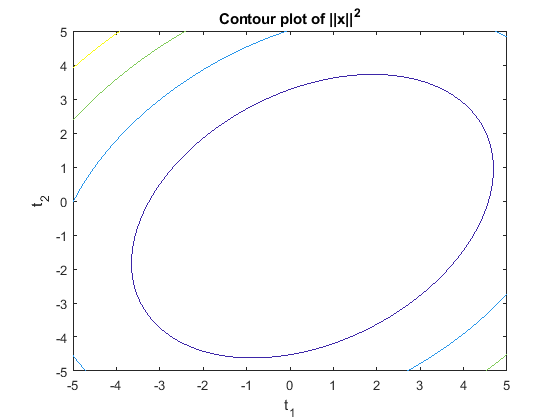

figure, fcontour(norm_sq), xlabel('t_1'), ylabel('t_2'), title('Contour plot of ||x||^2')

The squared norm is a quadratic function of the $t_i$, meaning it has a unique stationary point, which is found by setting its gradient to zero.

eq_sp = gradient(norm_sq) == 0

$$eq\_sp = \left(\begin{array}{c} 6\,t_{1}-2\,t_{2}-4=0\\ 6\,t_{2}-2\,t_{1}+\frac{26}{7}=0 \end{array}\right)$$

[t1, t2] = solve(eq_sp)

$$t1 = \frac{29}{56}$$

$$t2 = -\frac{25}{56}$$

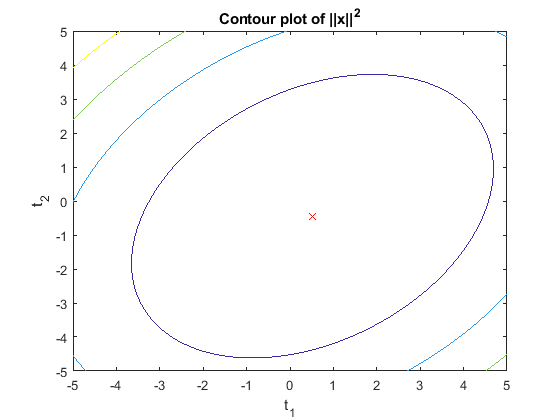

hold on, plot(t1, t2, 'rx') % x marks the spot!

Substituting these values of $t_1$ and $t_2$ into our general solution, we obtain the minimum norm solution.

x_min_nrm = subs(x_g, t, [t1;t2])

$$x\_min\_nrm = \left(\begin{array}{c} \frac{37}{28}\\ -\frac{45}{56}\\ \frac{29}{56}\\ \frac{7}{8}\\ -\frac{25}{56} \end{array}\right)$$

We can confirm this solution does have a smaller norm than our particular solution from earlier:

double(norm(x_p)), double(norm(x_min_nrm))

ans = 2.3430

ans = 1.9039

and indeed, by construction, it has a smaller norm than any other possible solution.

Where though, does this minimum norm solution come from?  There is a very nice argument that shows it is in fact the unique solution to $Ax = b$ that lies in the *row space* of $A$.  

[Video](https://web.microsoftstream.com/video/a9573071-8bd2-4172-a0ce-c4f125123bf9)

Remember that *any* vector $x \in \mathbb{R}^n$ can be written as $x = x_r + x_n$ with $x_r \in \textrm{rowspace}(A)$ and $x_n \in \textrm{nullspace}(A)$, since the row space and null space are orthogonal complements in $\mathbb{R}^n$.  But taking the squared norm of this vector $x$, we see that $\|x\|^2 = x \cdot x = (x_r + x_n) \cdot (x_r + x_n) = \|x_r\|^2 + \|x_n\|^2$  since $x_r \cdot x_n = 0$.  But when solving $Ax = b$ we are free to choose any vector in the null space we like, so the minimum norm solution comes from taking the null space component $x_n$ to be zero, leaving only $x = x_r$.  That is, the minimum norm solution is precisely the solution lying in the row space.

Hence, once we develop some more tools in our linear algebra arsenal in later chapters, there will be no need to wield calculus to solve problems like these.  The question of mimimum norm solutions is entirely within the realm of linear algebra.  Let's just check that indeed the solution we found using calculus lies in the row space.  The easiest way is probably just to show that it's *orthogonal* to the *null space*.

NS_basis' * x_min_nrm  % expect to get zero for x_min_nrm in rowspace(A)

$$ans = \left(\begin{array}{c} 0\\ 0 \end{array}\right)$$

In applications, sometimes solutions with as many zero elements as possible are desirable (like our $x_p$), sometimes solutions with minimum norm are desirable (i.e. $x_r$).  Either are likely to be more desirable than a solution like

subs(x_g, t, 1e20*[1;1])

$$ans = \left(\begin{array}{c} \frac{16}{7}\\ -\frac{700000000000000000002}{7}\\ 100000000000000000000\\ -\frac{699999999999999999997}{7}\\ 100000000000000000000 \end{array}\right)$$

but as far as the linear system is concerned, all are legitimate solutions.

#### Exercise

In the video above, we drew a diagram which assumed there was a *unique *solution $x_r$ in the row space of $A$.  But could there be more than one?  In this exercise you will prove that the answer is no.

Let $Ax = b$ be a consistent linear system.  Prove that the solution to this system which is in the row space of $A$ is unique.

Hint: try a proof by contradiction.  Start by assuming there were *two *distinct solutions in the row space, and see what that implies.▫

### 1.4.4 Column space revisited

Back to our rectangular matrix for one last look.

A

$$A = \left(\begin{array}{ccccc} 1 & -1 & 0 & 1 & 0\\ 1 & 0 & 1 & -3 & -4\\ 2 & 2 & 4 & 0 & -2\\ 1 & 0 & 1 & 2 & 1\\ 3 & 3 & 6 & 0 & -3\\ 0 & 2 & 2 & 2 & 2\\ 0 & 1 & 1 & 4 & 4\\ 3 & -2 & 1 & 2 & -1 \end{array}\right)$$

rank(A)

ans = 3

It's noticeable that $A$ is not of full rank.  "Full rank" in this case would mean a rank of 5: the number of columns.

Since the rank of $A$ is only 3, it must be that there are only three linearly independent columns.  The other two columns must therefore be expressible as linear combinations of these three.  This raises two questions:

- How can we identify which columns form a linearly independent set?

- How can we express the remaining columns in terms of these?

[Video](https://web.microsoftstream.com/video/304650bb-1076-4167-ab93-d49a5a47dd87)

Both questions are readily answered by looking at the RREF.

R = rref(A)

$$R = \left(\begin{array}{ccccc} 1 & 0 & 1 & 0 & -1\\ 0 & 1 & 1 & 0 & 0\\ 0 & 0 & 0 & 1 & 1\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0\\ 0 & 0 & 0 & 0 & 0 \end{array}\right)$$

In fact, the answer to the first question is just a matter of identifying the *basic columns*: those columns with the leading 1 for some row.  These are evidently columns 1, 2 and 4.  Sure enough, if you look back to our earlier solution to $Ax = b$, the basic variables were indeed $x_1$, $x_2$ and $x_4$.

So columns 3 and 5 of $A$ must be expressible as linear combinations of columns 1, 2 and 4.  Can we determine the coefficients in those linear combinations?  Yes.  Look at the top two entries in column 3 of $R$: 1 and 1.  This is telling you that column 3 = $1 \times$ column 1 + $1 \times$ column 2

isequal(A(:,3), A(:,1) + A(:,2))

ans = logical
   1


Similarly, the entries -1, 0, 1 in column 5 tell you that column 5 = $-1 \times$ column 1 + $0 \times$ column 2 + $1 \times$ column 4.

isequal(A(:,5), -A(:,1) + A(:,4))

ans = logical
   1


Do you see why?  Remember what we discussed in the video above: if you were given three vectors $v_1$, $v_2$ and $v_3$ and asked the question "what linear combination of vectors $v_1$ and $v_2$ give me $v_3$?", what linear system would you form and solve to find the answer?

Since there are only three linearly independent columns of $A$, it must be that their span *is *the column space of $A$.  So evidently, we could have found a basis for the column space of $A$ in a completely different way than we did earlier: simply identify the basic columns from the RREF, then grab those columns out of $A$.  Compare:

CS_basis % what we had before

$$CS\_basis = \left(\begin{array}{ccc} 1 & 0 & 0\\ 0 & 1 & 0\\ 0 & 0 & 1\\ \frac{5}{7} & -\frac{3}{7} & \frac{5}{14}\\ 0 & 0 & \frac{3}{2}\\ -\frac{4}{7} & -\frac{6}{7} & \frac{5}{7}\\ \frac{1}{7} & -\frac{9}{7} & \frac{4}{7}\\ \frac{17}{7} & \frac{1}{7} & \frac{3}{14} \end{array}\right)$$

CS_basis_2 = A(:, [1,2,4]) % using the basic columns of A

$$CS\_basis\_2 = \left(\begin{array}{ccc} 1 & -1 & 1\\ 1 & 0 & -3\\ 2 & 2 & 0\\ 1 & 0 & 2\\ 3 & 3 & 0\\ 0 & 2 & 2\\ 0 & 1 & 4\\ 3 & -2 & 2 \end{array}\right)$$

These two bases look nothing alike, but they *must* both span the same space: the column space of $A$.  Here's a quick way to confirm this fact:

rank([CS_basis CS_basis_2])  % find the rank of the two basis matrices augmented

ans = 3

The rank of the augmented matrices is still just 3: no new information is provided by `CS_basis_2` that wasn't already represented by `CS_basis`.  They're just different representations of the same space.  Both bases have their own advantages.  The first, `CS_basis`, has the nice one/zero structure in the top rows, which makes it perfectly clear that the three vectors are linearly independent.  The second, `CS_basis_2`, consists entirely of columns of $A$.

#### Exercise

Describe how you would build a basis for the *row space* of $A$ that consisted entirely of rows of $A$.

Try it out on the matrix above, either by hand(!) and/or using MATLAB.

Confirm your new basis spans the same space as the basis for the row space we found earlier.▫

## **1.5 Summary**

- Associated with every matrix $A \in \mathbb{R}^{m \times n}$ are four fundamental subspaces: the row space, the column space, the null space and the left null space.

- The four fundamental subspaces are related as follows:

-     The row space of $A$ and the null space of $A$ are orthogonal complements in $\mathbb{R}^n$.

-     The column space of $A$ and the null space of $A^T$ are orthogonal complements in $\mathbb{R}^m$.

- The rank, nullity and "left nullity" satisfy the following equations:

-     
$$\textrm{rank}(A) + \textrm{nullity}(A) = n$$


-     
$$\textrm{rank}(A) + \textrm{nullity}(A^T) = m$$


- A linear system $Ax = b$ can have zero, one or infinitely many solutions.

-     If rank($A$) = rank($[A\ b]$)  = $n$ the  system is consistent with a unique solution.

-     If rank($A$) = rank($[A\ b]$)  < $n$ the system is consistent with infinitely many solutions.

-     If rank($A$) $\neq$ rank($[A\ b]$)  the system is inconsistent.

- The general solution of a linear system $Ax = b$ is the sum of a particular solution to $Ax = b$ and the general solution to $Ax = 0$.

-     The minimum norm solution to $Ax = b$ is the unique vector $x_r \in \textrm{rowspace}(A)$ satisfying $Ax_r = b$.